# ECSE 343:Assignment 5

Name: **Hamza Abu Alkhair**

Student Id. **261040392**

Due Date: 17 April 2025

## Question 1

 You are given the following 3rd order differential equation,

                
$$y^{'''}(t) + 32 y^{''} (t) +61.25 y'(t)  + 37.5 y(t)  = sin(\frac{\pi t} {4})$$


a. Transform the above differential equation into a system of first-order differential equations. **(5 marks)**

- We can define some of the following things


$$
\[
x_1(t) = y(t), \quad x_2(t) = y'(t), \quad x_3(t) = y''(t)
\]
$$


- We then form equations based off of this where the variables are


$$
\[
x_1' = x_2 \\
x_2' = x_3 \\
x_3' = y^{‴}(t) = \sin\left(\frac{\pi}{4}\right) - 32x_3 - 61.25x_2 - 37.5x_1
\end{aligned}
\]$$


- The following system will be produced


$$
\[
\begin{cases}
x_1' = x_2 \\
x_2' = x_3 \\
x_3' = \sin\left(\frac{\pi}{4}\right) - 32x_3 - 61.25x_2 - 37.5x_1
\end{cases}
\]$$


b.  For the system of first order ODEs obtained in part a, apply the Backward Euler approximation for the derivative and write the obtained **difference Equations **below. **(5 marks)**

*        % type your answer here, write all the equations*

c.  You are provided with the initial conditions, $y(0) =0$, $y'(0) =1$, and  $y''(0) = 0$ for the given differential equation.  Use the cell below to implement the Backward Euler method to solve the first order ODE's obtained in part a . Run the simulation for $25s$, use the time step $\Delta t= 0.065s$.  

Plot  $y(t)$ vs $t$ on the same plot as the true solution, label your plots appropriately. **(5 marks)**


clear all
dT = 0.065; %sec
T = 0:dT:25; 

%-----------------------------------------------------------------------------
% write the your code here.












%------------------------------------------------------------------------------
load('q1_refSol.mat') % load true analytical sol for reference.

figure()
plot(Q1_Tref,Q1_ref_sol,'r-','LineWidth',2,'displayname','True Solution') % plots true solution for comparison
hold on 
%-------------------------------------------------------------------------------


% plot your solution here.
plot(T,y,'b--','LineWidth',1.5,'displayname','Backward Euler')
% Note: the variable y is the y(t).  You may choose to rename it according
% to your preference,.                                        
%--------------------------------------------------------------------------------                                                              
                                                              
xlabel('time')
ylabel('y')
grid on
legend("Location","best")

d.  Run the code you wrote in part c again, run the code for $25s$ and use the time step $\Delta t= 1s$.  Plot  $y(t)$ vs $t$ on the same plot as the true solution.

 Is the obtained solution more accurate than the solution in part c? Explain.  **(2 marks)**

*Note: You may copy the code you wrote in part c in the cell below to run it for *$\Delta t =1s$ 

% you may copy the code from part c here and run it for deltaT =1s

*% type your answer here*

e. For the system of first-order ODEs obtained in part a, use the Forward Euler approximation for the derivative and write the obtained difference Equations below. **(5 marks)**

*        %  type your answer here. Show all the equations and steps.*

f. Use the same initial conditions as part c (i.e. $y(0) =0$, $y'(0) =1$, and  $y''(0) = 0$).  Implement the Forward  Euler method to solve the first order ODE's obtained in part a . Run the simulation for $25s$, use the time step $\Delta t= 0.065s$.  Plot  $y(t)$ vs $t$ on the same plot as the true solution, label your plots appropriately. **(5 marks)**

Write your code in the cell below.

clear all
dT = 0.065; %sec
T = 0:dT:25; 

%-----------------------------------------------------------------------------
% write the your code here.












%------------------------------------------------------------------------------
load('q1_refSol.mat') % load true analytical sol for reference.

figure()
plot(Q2_Tref,Q2_ref_sol,'r-','LineWidth',2,'displayname','True Solution') % plots true solution for comparison
hold on 
%-------------------------------------------------------------------------------


% plot your solution here.
plot(T,y,'b--','LineWidth',1.5,'displayname','Backward Euler')
% Note: the variable y is the y(t).  You may choose to rename it according
% to your preference,.                                        
%--------------------------------------------------------------------------------                                                              
                                                              
xlabel('time')
ylabel('y')
grid on
legend("Location","best")

g. Run the code you wrote in part f again, run the code for $25s$ and use the time step $\Delta t= 0.068s$.  Plot  $y(t)$ vs $t$ on the same plot as the true solution.

*Note: You may copy the code you wrote in part f in the cell below to run it for *$\Delta t =0.068s$ 

Comment on the solutions obtained in part e and f. **(2 marks)**

% you may copy the code from part c here and run it for deltaT =1s

*% you can type  your comments  here.*

**Question 2: **

 The circuit shown below is called the Half-Wave Rectifier. For this circuit we will compute the transient response of the circuit for all the voltage nodes, namely, V1, V2 and V3.  

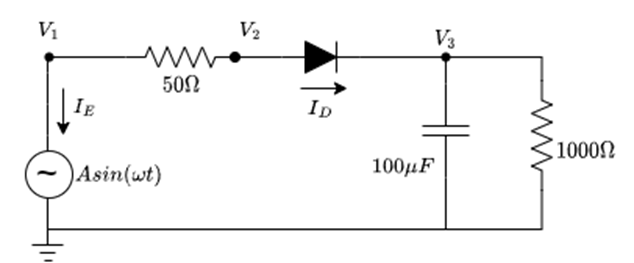

IE is the current passing into voltage source. ID is the diode current shown as 


$$I_D =I_{S\;} \left(e^{\frac{\left(V_2 -V_3 \right)}{\textrm{Vt}\;}} -1\right)$$


 Is is the saturation current of the diode and $V_t$ is the thermal voltage. As we can see that the diode current is a nonlinear function of the node voltages $V_2$ and $V_3$, this makes the nodal equations of the above circuit is nonlinear.

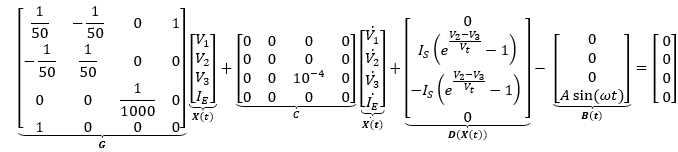

The above equation can be written in compact form as, 


$$\mathit{\mathbf{F}}\left(\mathit{\mathbf{X}}\left(t\right)\right)=\mathit{\mathbf{G}}\;\mathit{\mathbf{X}}\left(t\right)+\mathit{\mathbf{C}}\;\dot{\mathit{\mathbf{X}}\left(\mathit{\mathbf{t}}\right)} +\mathit{\mathbf{D}}\left(\mathit{\mathbf{X}}\left(\mathit{\mathbf{t}}\right)\right)-\mathit{\mathbf{B}}\left(t\right)=0$$


The expression in (3) represents system of Nonlinear Differential Algebraic equations. The solution vector $\textbf{X}(t)$  and the input vector $\textbf{B}(t)$  are time varying.  At time,  ,  $\textbf{X}(t)$ and $\textbf{B}(t)$ can be written as $\textbf{X}_n$ and $\textbf{B}_n$, respectively.

 
$$\mathit{\mathbf{F}}\left({\mathit{\mathbf{X}}}_n \right)=\mathit{\mathbf{G}}\;{\mathit{\mathbf{X}}}_n +\mathit{\mathbf{C}}\;\dot{{\mathit{\mathbf{X}}}_n } +\mathit{\mathbf{D}}\left({\mathit{\mathbf{X}}}_n \right)-{\mathit{\mathbf{B}}}_n =0$$


Use the Backward Euler formula and the Newton-Raphson method to find the transient solution for this circuit. The use transient voltage source with amplitude equal to 5V with the frequency of 60Hz. Use saturation current for the diode, $I_S = 10^{-13} A$ and the thermal voltage of the diode, $V_t = 0.025 V$. Simulate, the circuit for 0.5s with the time step, $\Delta t = 10^{-4}s$  Use the tolerance value, $\epsilon_{tol} = 10^{-5}$, to check for convergence of the Newton-Raphson. Plot the obtained solution for $V_1$,$V_2$, and $V_3$

% write your code below. you can also use the appendix to write any
% functions if necessary

## Question 3 :  

a. Write  steepest descent algorithm to solve  linear system of equations given by  $\textbf A \textbf x = \textbf b$,  where $\textbf A \in \mathbb{R}^{n \times n}$ is a symmetric and positive definite matrix, $\textbf b \in \mathbb{R}^{n \times 1}$ and $\textbf x \in \mathbb{R}^{n \times 1}$. You can implement the maethod in the appendix. (10 marks)

% Write your code in the appendix.

b. In this question, you will solve the matrix systems of size ranging for n= 2, 3, 4 , 5, ..., 100 .  Use the function named *getSystemMatrix_with_lowerConditionNumber* (provided in the appendix) to  generate the system matrix $\textbf A$ and the vector $\textbf b$ of  size n.  The matrix $\textbf A$ generated by the *getSystemMatrix.m* has a good condition number.

Use the LU decomposition based method( you wrote in earlier assignments ) and the steepest descent method  to compute the solution of linear system with size ranging from n =2  to 100.  Plot the time taken to compute the solution by the LU decompostion based method vs the matrix size. On the same figure, plot the time taken by Steepest Descent method to find the solution.  Label the axes of the plot and include the legend.

Which method takes more time to compute the solution?

Use the cell below to write your code. For measuring  the time taken by each method you can use the code provided in part  b and then change it accordingly.   (8 marks)

clear all
% write your code here 

% demo of how to use the method  getSystemMatrix_with_lowerConditionNumber
% for n=2

n = 2; % matrix size.
[A , b] = getSystemMatrix(n);


## Appendix 

function [A,b]= getSystemMatrix(n)
%  n is the size of the matrix .
% outputs: A square matrix of size n times n
%          b  vector of size n.


    rng(0);
    density =10/n;
    R = sprand(n,n,density,0.25);
    A= R'*R;
    b = rand(n,1);
end

Write your steepest descent here.

function [x, iter] = my_steepest_descent(A, b, Xguess, tol, maxiter)
% inputs: A- a symmeteric and positiv definite matrix.
%         b : RHS vector
%        Xguess: Initial guess 
%        tol : tolerance 
%         maxiter:maximum iterations 

%outputs:  x: solution of the system Ax =b
%          iter: number of iterations it took to converge


end

